## Setup & Data Loading

%% =========================================================================
% SETUP & DATA LOADING
% =========================================================================
% Adds the NIfTI tools to the MATLAB path so load_untouch_nii is available.
% All subject data lives in dataPath, shared metadata (TEs.txt) in metadataPath.

addpath('./matlab/nifti_tools/')

dataPath     = './data-adolescent/';   % <-- CHANGE THIS to your local path
metadataPath = './metadata/';

% ── Echo times ────────────────────────────────────────────────────────────
% TEs.txt contains the 10 non-uniform spin-echo times (ms) shared across
% all subjects: 13, 16, 20, 25, 30, 40, 50, 85, 100, 150
% The large gap between 50ms and 85ms is important: by TE=85ms many voxels
% are near the Rician noise floor, which causes non-monotonic behaviour.
TEs = load(fullfile(metadataPath, 'TEs.txt'))';
nTE = length(TEs);
fprintf('Echo times loaded (%d TEs): %s ms\n', nTE, num2str(TEs'));

Echo times loaded (10 TEs): 13   16   20   25   30   40   50   85  100  150 ms



% ── Subject discovery ─────────────────────────────────────────────────────
% Automatically finds all Epicure subjects in dataPath by scanning for
% registered qt2 files. Falls back to unregistered if none found.
allFiles = dir(fullfile(dataPath, 'Epicure*-qt2_reg.nii.gz'));
if isempty(allFiles)
    allFiles = dir(fullfile(dataPath, 'Epicure*-qt2.nii.gz'));
end
nSubj = length(allFiles);
fprintf('Found %d subjects\n', nSubj);

Found 143 subjects



% Extract the Epicure ID from each filename (e.g. 'Epicure13267')
subjectIDs = cell(nSubj, 1);
for s = 1:nSubj
    tok = regexp(allFiles(s).name, '(Epicure\d+)', 'tokens', 'once');
    subjectIDs{s} = tok{1};
    fprintf('  Subject %d: %s\n', s, subjectIDs{s});
end

  Subject 1: Epicure11610
  Subject 2: Epicure13267
  Subject 3: Epicure13620
  Subject 4: Epicure14121
  Subject 5: Epicure14416
  Subject 6: Epicure15516
  Subject 7: Epicure15757
  Subject 8: Epicure16926
  Subject 9: Epicure17065
  Subject 10: Epicure18966
  Subject 11: Epicure21302
  Subject 12: Epicure21511
  Subject 13: Epicure22313
  Subject 14: Epicure22598
  Subject 15: Epicure23128
  Subject 16: Epicure23140
  Subject 17: Epicure24217
  Subject 18: Epicure24300
  Subject 19: Epicure25316
  Subject 20: Epicure25985
  Subject 21: Epicure26132
  Subject 22: Epicure27155
  Subject 23: Epicure28717
  Subject 24: Epicure28999
  Subject 25: Epicure30002
  Subject 26: Epicure30142
  Subject 27: Epicure30750
  Subject 28: Epicure31084
  Subject 29: Epicure32437
  Subject 30: Epicure33936
  Subject 31: Epicure34160
  Subject 32: Epicure35162
  Subject 33: Epicure35837
  Subject 34: Epicure35893
  Subject 35: Epicure36152
  Subject 36: Epicure36395
  Subject 37: Epicure36559
  Subject 


% ── Data integrity check ──────────────────────────────────────────────────
% Store original file sizes before any processing. Compared again at the
% end of Task 4 to confirm source .nii.gz files were never modified.
% (Safe because gunzip always writes to tempdir, never back to dataPath.)
origFiles = dir(fullfile(dataPath, 'Epicure*-qt2_reg.nii.gz'));
origSizes = [origFiles.bytes];
fprintf('Original .nii.gz file sizes stored for verification\n');

Original .nii.gz file sizes stored for verification


## Task 1 - Exploration

%% =========================================================================
% TASK 1: DATA EXPLORATION
% =========================================================================
% Investigates signal quality and whether the data satisfies the assumptions
% of the exponential decay model S(TE) = S0 * exp(-TE/T2):
%   (a) Visualise signal decay across all 10 TEs
%   (b) Single-voxel decay on linear and log scale
%   (c) Monotonicity check across all subjects (key artefact indicator)
%   (d) Mean decay curve per tissue class

% Class names confirmed by visual inspection (see seg class check figures)
classNames = {'Unknown', 'Extra-CSF', 'GM', 'WM', 'Deep GM', 'Other'};

% Load first subject for all single-subject visualisations
% (change index to explore other subjects)
subj1 = subjectIDs{1};
[img1, mask1, seg1] = loadSubject(dataPath, subj1);

% Define representative slices for 2D visualisation
midSlice    = round(size(img1, 3) / 2);     % middle of the brain (z~25)
bottomSlice = round(size(img1, 3) / 4);     % lower brain, ~25% from bottom

fprintf('\n=== Subject: %s ===\n', subj1);


=== Subject: Epicure11610 ===


fprintf('Volume size : %d x %d x %d (%d echoes)\n', ...
        size(img1,1), size(img1,2), size(img1,3), nTE);

Volume size : 96 x 96 x 51 (10 echoes)


fprintf('Brain voxels: %d\n', sum(mask1(:)));

Brain voxels: 63631


fprintf('Tissue classes: %s\n', num2str(unique(seg1(mask1))'));

Tissue classes: 2  3  4  5  6


fprintf('midSlice=%d  bottomSlice=%d\n', midSlice, bottomSlice);

midSlice=26  bottomSlice=13


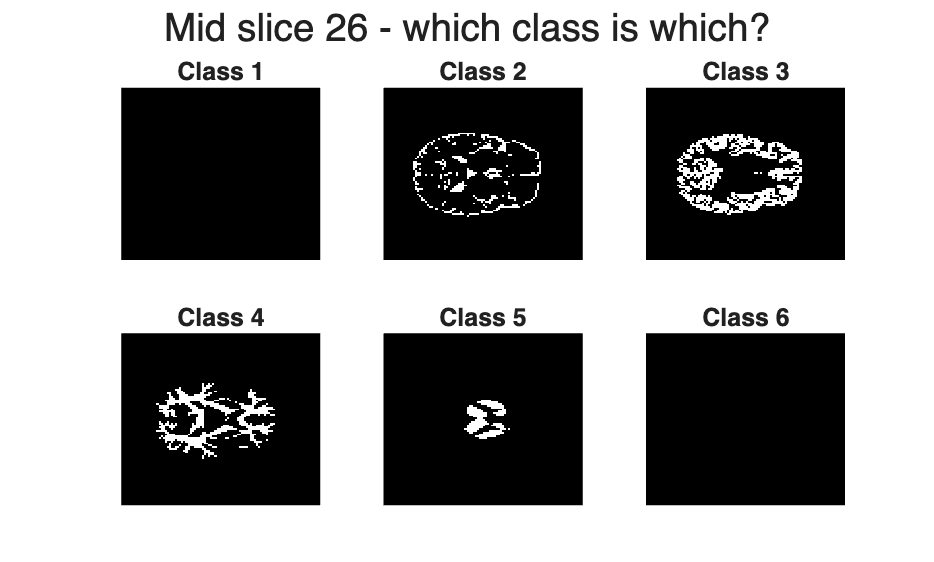


% ── Segmentation class verification ───────────────────────────────────────
% Plot each class as a binary mask at two slice levels to confirm the
% anatomical mapping. Compare against the T2 images in Task1a.
figure('Name', 'Seg class check - midSlice');
for c = 1:6
    subplot(2,3,c);
    imagesc(seg1(:,:,midSlice) == c);
    colormap gray; axis off;
    title(sprintf('Class %d', c));
end
sgtitle(sprintf('Mid slice %d - which class is which?', midSlice));

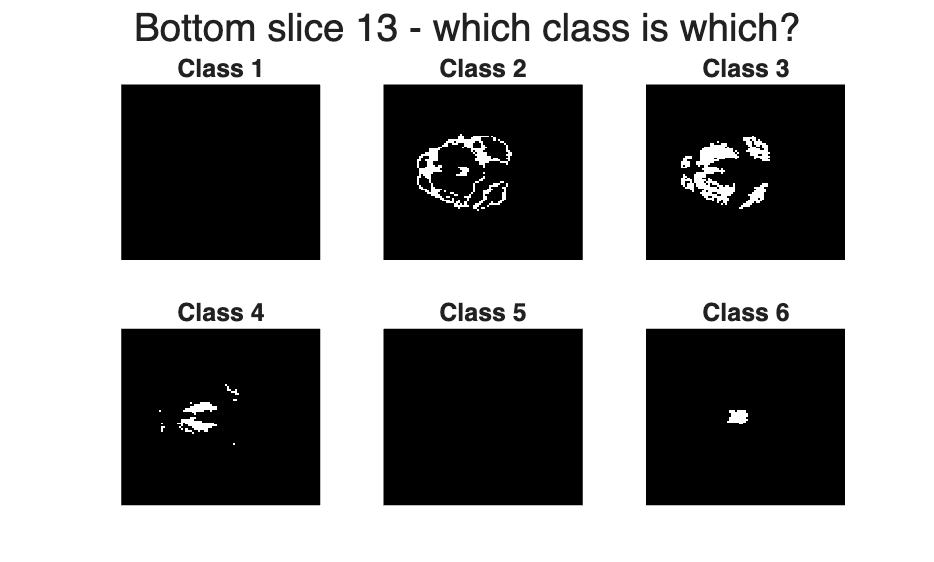


figure('Name', 'Seg class check - bottomSlice');
for c = 1:6
    subplot(2,3,c);
    imagesc(seg1(:,:,bottomSlice) == c);
    colormap gray; axis off;
    title(sprintf('Class %d', c));
end
sgtitle(sprintf('Bottom slice %d - which class is which?', bottomSlice));

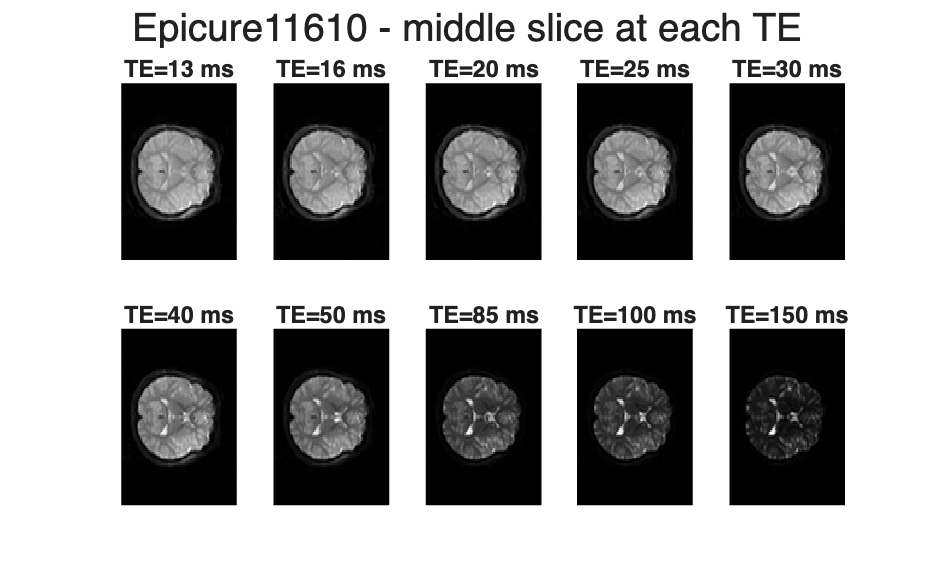


% ── (a) Middle slice at each TE ───────────────────────────────────────────
% As TE increases signal decays due to T2 relaxation. WM decays fastest
% (short T2 ~70ms), CSF persists longest (long T2 ~2000ms).
% The jump in darkness between TE=50ms and TE=85ms reflects the large
% gap in the non-uniform echo spacing.
figure('Name', 'Task1a - T2 decay across TEs');
for i = 1:nTE
    subplot(2, ceil(nTE/2), i);
    imagesc(img1(:,:,midSlice,i));
    colormap gray; axis off;
    title(sprintf('TE=%.0f ms', TEs(i)));
end
sgtitle(sprintf('%s - middle slice at each TE', subj1));

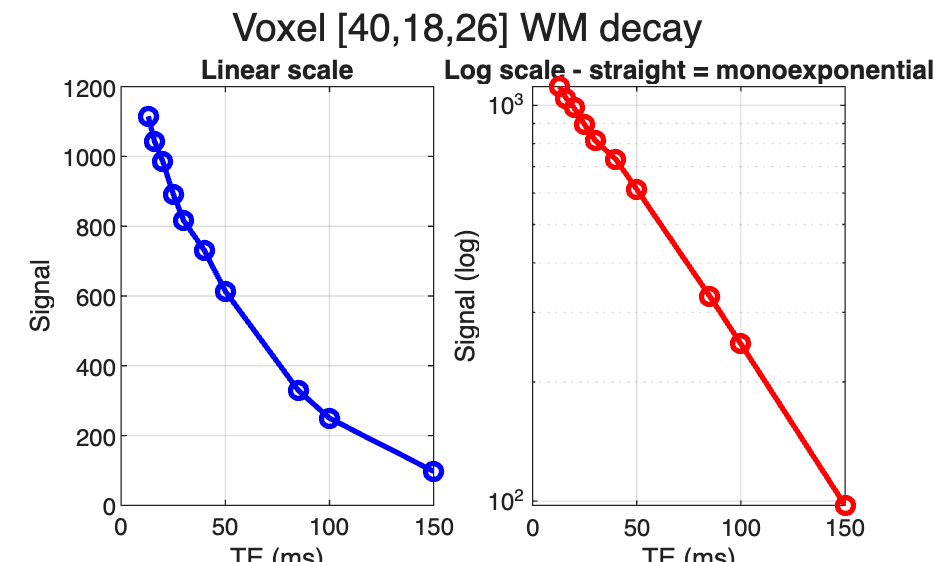


% ── (b) Single-voxel decay: linear and log scale ──────────────────────────
% Automatically selects the first WM voxel (class 4) at the middle slice.
% Linear scale: should show smooth exponential decrease.
% Log scale: if decay is truly monoexponential, log(S) vs TE is a straight
% line. Curvature indicates multiexponential behaviour (multiple compartments)
% which motivates the two-compartment model in Task 3.
WM_class = 4;
wm_vox = find(seg1(:,:,midSlice) == WM_class, 1);
if isempty(wm_vox)
    wm_vox = find(mask1(:,:,midSlice), 1);  % fallback to any brain voxel
end
[xv, yv] = ind2sub([size(img1,1), size(img1,2)], wm_vox);
zv = midSlice;
signal_vox = squeeze(img1(xv, yv, zv, :));

figure('Name', 'Task1b - Single voxel decay');
subplot(1,2,1);
plot(TEs, signal_vox, 'bo-', 'LineWidth', 2);
xlabel('TE (ms)'); ylabel('Signal'); title('Linear scale'); grid on;

subplot(1,2,2);
semilogy(TEs, max(signal_vox, 1e-6), 'ro-', 'LineWidth', 2);
xlabel('TE (ms)'); ylabel('Signal (log)');
title('Log scale - straight = monoexponential'); grid on;
sgtitle(sprintf('Voxel [%d,%d,%d] WM decay', xv, yv, zv));


% ── (c) Monotonicity check across all subjects ────────────────────────────
% A voxel is non-monotonic if its signal INCREASES between any consecutive
% TE pair. This violates the exponential decay assumption.
%
% Main cause in this dataset: Rician noise floor. At long TEs (85-150ms)
% the true signal is very weak and MRI magnitude noise adds a positive bias
% that can exceed the signal, causing apparent increases.
%
% High non-monotonic % → fitting unreliable at long TEs → affects T2 accuracy.
% Each subject uses its own nTE_i because some subjects have 8 not 10 echoes.
fprintf('\n%-15s  %-14s  %-22s\n', 'Subject', '% non-mono', 'Median signal @ last TE');


Subject          % non-mono      Median signal @ last TE


pctNM = zeros(nSubj, 1);

for si = 1:nSubj
    [imgi, maski, ~] = loadSubject(dataPath, subjectIDs{si});

    nTE_i = size(imgi, 4);  % use actual number of volumes for this subject
    fprintf('  %s has %d volumes\n', subjectIDs{si}, nTE_i);

    nmono = false(size(maski));
    for k = 1:nTE_i-1
        v1 = imgi(:,:,:,k);
        v2 = imgi(:,:,:,k+1);
        nmono = nmono | (v2 > v1 & maski);  % flag voxels that go up
    end
    pctNM(si) = 100 * sum(nmono(:)) / max(sum(maski(:)), 1);

    % Median signal at last echo: proxy for noise floor level
    lastVol = imgi(:,:,:,end);
    nf = median(lastVol(maski));
    fprintf('%-15s  %5.1f%%         %.1f\n', subjectIDs{si}, pctNM(si), nf);
end

  Epicure11610 has 10 volumes


Epicure11610      17.0%         195.9


  Epicure13267 has 10 volumes


Epicure13267      13.6%         174.8


  Epicure13620 has 10 volumes


Epicure13620      17.2%         176.9


  Epicure14121 has 10 volumes


Epicure14121      19.5%         198.4


  Epicure14416 has 10 volumes


Epicure14416      31.5%         185.1


  Epicure15516 has 10 volumes


Epicure15516      30.3%         202.7


  Epicure15757 has 10 volumes


Epicure15757      30.0%         220.0


  Epicure16926 has 10 volumes


Epicure16926      17.3%         169.8


  Epicure17065 has 10 volumes


Epicure17065      88.0%         226.5


  Epicure18966 has 10 volumes


Epicure18966      43.7%         201.9


  Epicure21302 has 10 volumes


Epicure21302      43.4%         214.0


  Epicure21511 has 10 volumes


Epicure21511      21.5%         193.2


  Epicure22313 has 10 volumes


Epicure22313      14.5%         182.7


  Epicure22598 has 10 volumes


Epicure22598      31.5%         205.6


  Epicure23128 has 10 volumes


Epicure23128      25.1%         203.7


  Epicure23140 has 10 volumes


Epicure23140      27.6%         199.6


  Epicure24217 has 10 volumes


Epicure24217      13.9%         184.7


  Epicure24300 has 10 volumes


Epicure24300      34.0%         207.8


  Epicure25316 has 10 volumes


Epicure25316      31.7%         171.3


  Epicure25985 has 10 volumes


Epicure25985      42.7%         177.8


  Epicure26132 has 10 volumes


Epicure26132      39.9%         195.5


  Epicure27155 has 10 volumes


Epicure27155      21.7%         178.1


  Epicure28717 has 10 volumes


Epicure28717      18.0%         197.4


  Epicure28999 has 10 volumes


Epicure28999      16.6%         184.4


  Epicure30002 has 10 volumes


Epicure30002      41.1%         193.3


  Epicure30142 has 10 volumes


Epicure30142      24.4%         196.0


  Epicure30750 has 10 volumes


Epicure30750      17.7%         187.6


  Epicure31084 has 10 volumes


Epicure31084      13.2%         176.0


  Epicure32437 has 10 volumes


Epicure32437      58.5%         203.4


  Epicure33936 has 10 volumes


Epicure33936      24.1%         175.8


  Epicure34160 has 10 volumes


Epicure34160      14.7%         189.0


  Epicure35162 has 10 volumes


Epicure35162      18.0%         180.4


  Epicure35837 has 10 volumes


Epicure35837      20.3%         200.9


  Epicure35893 has 10 volumes


Epicure35893      23.1%         182.0


  Epicure36152 has 10 volumes


Epicure36152      41.2%         193.5


  Epicure36395 has 10 volumes


Epicure36395      17.6%         179.3


  Epicure36559 has 10 volumes


Epicure36559      22.7%         202.4


  Epicure36577 has 10 volumes


Epicure36577      11.1%         168.7


  Epicure36937 has 10 volumes


Epicure36937      24.6%         178.3


  Epicure37648 has 10 volumes


Epicure37648      43.8%         189.7


  Epicure37808 has 10 volumes


Epicure37808      37.2%         145.2


  Epicure38475 has 10 volumes


Epicure38475      31.3%         191.1


  Epicure38479 has 10 volumes


Epicure38479      41.4%         191.1


  Epicure39341 has 10 volumes


Epicure39341      16.4%         157.5


  Epicure39887 has 10 volumes


Epicure39887      30.7%         171.9


  Epicure40818 has 10 volumes


Epicure40818      15.1%         197.3


  Epicure42259 has 10 volumes


Epicure42259      21.0%         173.3


  Epicure42959 has 10 volumes


Epicure42959      26.4%         186.3


  Epicure43105 has 10 volumes


Epicure43105      50.1%         201.4


  Epicure43203 has 10 volumes


Epicure43203      29.3%         172.4


  Epicure43607 has 10 volumes


Epicure43607      16.3%         177.4


  Epicure44254 has 10 volumes


Epicure44254      14.4%         212.8


  Epicure44631 has 8 volumes


Epicure44631      15.5%         188.3


  Epicure45148 has 10 volumes


Epicure45148      47.1%         200.4


  Epicure45195 has 10 volumes


Epicure45195      22.3%         191.1


  Epicure45442 has 10 volumes


Epicure45442      24.8%         189.2


  Epicure45858 has 10 volumes


Epicure45858      20.2%         221.2


  Epicure46431 has 10 volumes


Epicure46431      28.1%         188.5


  Epicure46558 has 10 volumes


Epicure46558      27.0%         191.9


  Epicure46831 has 10 volumes


Epicure46831      15.1%         181.8


  Epicure47318 has 10 volumes


Epicure47318      63.9%         198.3


  Epicure47476 has 10 volumes


Epicure47476      33.2%         193.4


  Epicure47719 has 10 volumes


Epicure47719      21.9%         208.1


  Epicure47931 has 10 volumes


Epicure47931      14.6%         176.8


  Epicure48142 has 10 volumes


Epicure48142      37.5%         179.6


  Epicure48536 has 10 volumes


Epicure48536      14.1%         173.8


  Epicure48775 has 10 volumes


Epicure48775      12.2%         181.8


  Epicure48996 has 10 volumes


Epicure48996      53.2%         182.6


  Epicure49479 has 10 volumes


Epicure49479      32.4%         206.2


  Epicure49589 has 10 volumes


Epicure49589      34.9%         161.0


  Epicure49706 has 10 volumes


Epicure49706      47.7%         173.0


  Epicure50493 has 10 volumes


Epicure50493      27.8%         184.2


  Epicure50523 has 10 volumes


Epicure50523      53.1%         181.1


  Epicure50846 has 10 volumes


Epicure50846      26.3%         191.1


  Epicure51795 has 10 volumes


Epicure51795      15.2%         187.7


  Epicure52422 has 10 volumes


Epicure52422      22.4%         187.5


  Epicure52653 has 10 volumes


Epicure52653      16.3%         173.0


  Epicure53459 has 10 volumes


Epicure53459      14.0%         189.1


  Epicure55894 has 10 volumes


Epicure55894      13.2%         171.7


  Epicure56643 has 10 volumes


Epicure56643      39.3%         189.8


  Epicure58846 has 10 volumes


Epicure58846      17.5%         188.3


  Epicure59011 has 10 volumes


Epicure59011      12.9%         188.7


  Epicure60112 has 10 volumes


Epicure60112      34.5%         183.3


  Epicure60962 has 10 volumes


Epicure60962      11.5%         183.7


  Epicure62078 has 10 volumes


Epicure62078      19.1%         194.1


  Epicure62943 has 10 volumes


Epicure62943      24.9%         189.0


  Epicure63959 has 10 volumes


Epicure63959      19.6%         176.9


  Epicure65088 has 10 volumes


Epicure65088      14.3%         177.8


  Epicure65750 has 10 volumes


Epicure65750      22.0%         180.8


  Epicure65751 has 10 volumes


Epicure65751      23.9%         165.2


  Epicure66036 has 10 volumes


Epicure66036      20.5%         212.5


  Epicure66302 has 10 volumes


Epicure66302      28.0%         182.5


  Epicure66610 has 10 volumes


Epicure66610      26.8%         192.9


  Epicure66734 has 10 volumes


Epicure66734      43.6%         223.0


  Epicure67358 has 10 volumes


Epicure67358      44.8%         165.8


  Epicure67504 has 10 volumes


Epicure67504      34.1%         186.7


  Epicure68990 has 10 volumes


Epicure68990      47.0%         183.1


  Epicure69131 has 10 volumes


Epicure69131      27.7%         173.6


  Epicure69241 has 10 volumes


Epicure69241      16.6%         185.5


  Epicure70915 has 10 volumes


Epicure70915      35.3%         182.5


  Epicure71479 has 10 volumes


Epicure71479      25.3%         187.3


  Epicure71935 has 10 volumes


Epicure71935      42.4%         180.0


  Epicure71981 has 10 volumes


Epicure71981      38.8%         172.7


  Epicure72993 has 10 volumes


Epicure72993      15.9%         189.5


  Epicure74067 has 2 volumes


Epicure74067      13.7%         1186.4


  Epicure74131 has 10 volumes


Epicure74131      14.5%         194.2


  Epicure74343 has 10 volumes


Epicure74343      24.7%         193.7


  Epicure76780 has 10 volumes


Epicure76780      14.6%         181.2


  Epicure76797 has 10 volumes


Epicure76797      10.5%         190.1


  Epicure78004 has 7 volumes


Epicure78004      32.5%         592.5


  Epicure78130 has 10 volumes


Epicure78130      42.5%         216.0


  Epicure78978 has 10 volumes


Epicure78978      17.6%         208.4


  Epicure79717 has 10 volumes


Epicure79717      17.5%         173.9


  Epicure79815 has 10 volumes


Epicure79815      28.6%         187.8


  Epicure80621 has 10 volumes


Epicure80621      21.9%         199.0


  Epicure80643 has 10 volumes


Epicure80643      26.2%         206.9


  Epicure80743 has 10 volumes


Epicure80743      26.6%         166.3


  Epicure81324 has 10 volumes


Epicure81324      20.3%         207.1


  Epicure81555 has 10 volumes


Epicure81555      27.4%         196.4


  Epicure81926 has 10 volumes


Epicure81926      28.3%         196.8


  Epicure82329 has 10 volumes


Epicure82329      66.4%         175.2


  Epicure82343 has 10 volumes


Epicure82343      29.5%         211.9


  Epicure82845 has 10 volumes


Epicure82845      34.0%         180.2


  Epicure83677 has 10 volumes


Epicure83677      16.3%         190.4


  Epicure83747 has 10 volumes


Epicure83747      43.3%         183.6


  Epicure85253 has 10 volumes


Epicure85253      17.1%         187.7


  Epicure85411 has 10 volumes


Epicure85411      23.9%         189.9


  Epicure85904 has 10 volumes


Epicure85904      15.9%         181.3


  Epicure85981 has 10 volumes


Epicure85981      32.7%         195.2


  Epicure88031 has 10 volumes


Epicure88031      53.8%         222.0


  Epicure88335 has 10 volumes


Epicure88335      17.9%         155.9


  Epicure91922 has 10 volumes


Epicure91922      38.8%         170.1


  Epicure92050 has 10 volumes


Epicure92050      15.0%         209.2


  Epicure92267 has 10 volumes


Epicure92267      19.5%         191.4


  Epicure92452 has 10 volumes


Epicure92452      20.3%         219.9


  Epicure94749 has 10 volumes


Epicure94749      32.1%         195.1


  Epicure95012 has 10 volumes


Epicure95012      22.0%         178.0


  Epicure96179 has 10 volumes


Epicure96179      35.3%         225.2


  Epicure96349 has 10 volumes


Epicure96349      17.1%         195.9


  Epicure96989 has 10 volumes


Epicure96989      47.3%         166.0


  Epicure98394 has 10 volumes


Epicure98394      18.4%         198.5


  Epicure98774 has 10 volumes


Epicure98774      20.6%         180.7


  Epicure98865 has 20 volumes


Epicure98865      15.3%         188.2


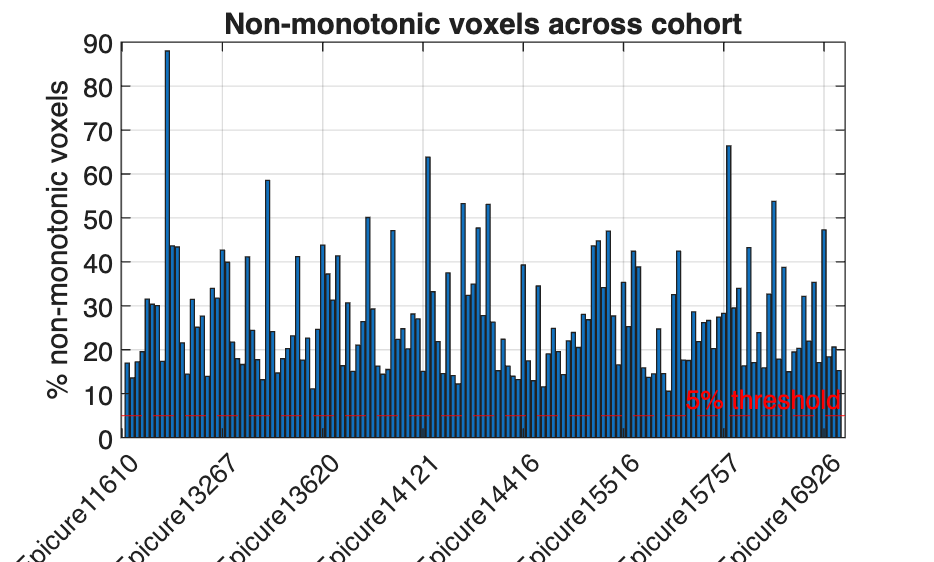


figure('Name', 'Task1c - Artefact indicator');
bar(pctNM);
set(gca, 'XTickLabel', subjectIDs, 'XTickLabelRotation', 45);
ylabel('% non-monotonic voxels');
yline(5, 'r--', '5% threshold');
title('Non-monotonic voxels across cohort'); grid on;

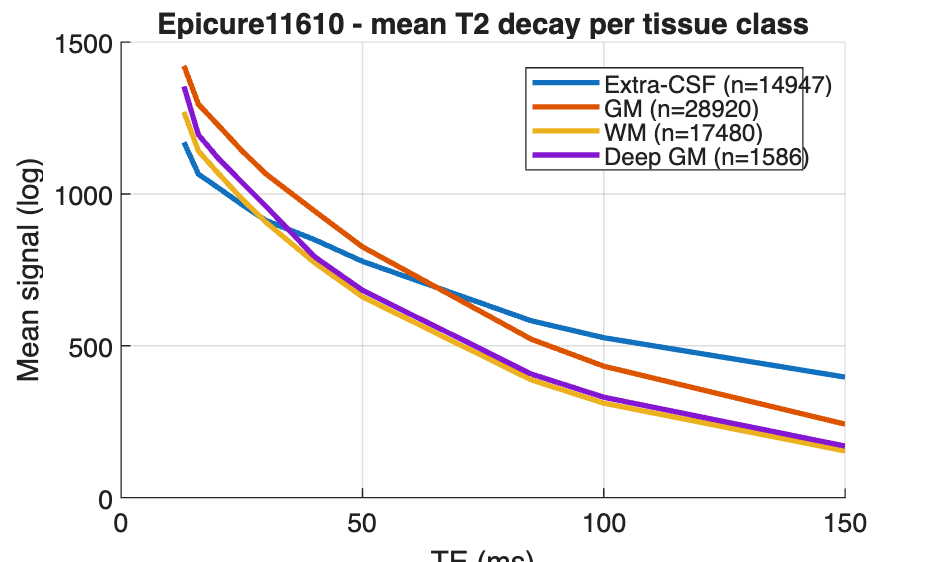


% ── (d) Mean decay per tissue class ───────────────────────────────────────
% Plots mean signal across all voxels of each class on a log scale.
% Expected behaviour:
%   WM (class 4):      steepest slope → shortest T2 (~70ms)
%   GM (class 3):      moderate slope → medium T2 (~80-100ms)
%   Extra-CSF (class 2): shallowest slope → longest T2 (~500ms+)
%   Deep GM (class 5): intermediate between WM and GM
% Well-separated lines confirm the segmentation is working correctly.
% Classes 1 and 6 are excluded as they are nearly empty across all subjects.
tissueLabels = unique(seg1(mask1));
tissueLabels = tissueLabels(tissueLabels > 1 & tissueLabels < 6);
colors = lines(length(tissueLabels));

figure('Name', 'Task1d - Mean decay per tissue class');
hold on;
for k = 1:length(tissueLabels)
    t      = tissueLabels(k);
    voxIdx = find(seg1 == t & mask1);
    meanSig = zeros(1, nTE);
    for te = 1:nTE
        vol = img1(:,:,:,te);
        meanSig(te) = mean(vol(voxIdx));
    end
    lbl = classNames{min(t, length(classNames))};
    semilogy(TEs, meanSig, 'Color', colors(k,:), 'LineWidth', 2, ...
             'DisplayName', sprintf('%s (n=%d)', lbl, length(voxIdx)));
end
xlabel('TE (ms)'); ylabel('Mean signal (log)');
legend('Location', 'best'); grid on;
title(sprintf('%s - mean T2 decay per tissue class', subj1));


% Noise floor estimate: median signal at the last (longest) echo.
% If this is comparable to signal at shorter TEs, fitting will be unreliable.
noiseFloor = median(img1(:,:,:,end), 'all');
fprintf('\nNoise floor (median signal at TE=%.0fms): %.1f\n', TEs(end), noiseFloor);


Noise floor (median signal at TE=150ms): 0.0


## Helper Function

%% =========================================================================
% HELPER FUNCTION: loadSubject
% =========================================================================
% Loads the T2 image, brain mask and tissue segmentation for one subject.
%
% INPUTS:
%   dataPath  - folder containing all Epicure NIfTI files
%   subjID    - subject string e.g. 'Epicure13267'
%
% OUTPUTS:
%   img  - [x,y,z,TE] double array of T2-weighted signal (negatives clipped)
%   mask - [x,y,z] logical brain mask (1=brain, 0=background)
%   seg  - [x,y,z] integer tissue label map (0=background, 1-6=tissue class)
%
% FILE NAMING CONVENTION (Andrew's cmbi_data folder):
%   EpicureXXXXX-qt2_reg.nii.gz   4D registered multi-echo T2 image
%   EpicureXXXXX-mask1.nii.gz     binary brain mask
%   EpicureXXXXX-qt2_seg1.nii.gz  6-class tissue segmentation (4D prob map)
%
% NOTE ON SEGMENTATION FORMAT:
%   qt2_seg1 is a 4D probability map [x,y,z,6]. Each of the 6 volumes gives
%   the probability of that voxel belonging to that tissue class. Values
%   sum to 1 across classes but can be slightly negative due to the
%   regression-based segmentation algorithm (safe to ignore).
%   We convert to a hard label map by taking the argmax across dim 4.
%
% CONFIRMED CLASS MAPPING (verified by visual inspection of anatomy):
%   Class 1 - Unknown   (~empty, excluded from analysis)
%   Class 2 - Extra-CSF (large sulcal/ventricular CSF)
%   Class 3 - GM        (cortical grey matter)
%   Class 4 - WM        (white matter)
%   Class 5 - Deep GM   (subcortical: thalamus, basal ganglia)
%   Class 6 - Other     (~empty, excluded from analysis)

function [img, mask, seg] = loadSubject(dataPath, subjID)

    function nii = safeLoad(filepath)
        % Decompress .nii.gz to a temp folder, load, then delete immediately.
        % onCleanup guarantees the temp file is deleted even if loading crashes,
        % ensuring the tempdir never accumulates stale files.
        tmpDir   = tempdir;
        outFiles = gunzip(filepath, tmpDir);
        unzipped = outFiles{1};
        cleanup  = onCleanup(@() delete(unzipped));
        nii      = load_untouch_nii(unzipped);
        % Note: load_untouch_nii bypasses the affine matrix check in load_nii,
        % which is necessary because these files have non-orthogonal headers.
    end

    % ── Load 4D T2 image ──────────────────────────────────────────────────
    % Prefer the motion-corrected registered version if available.
    f_reg = fullfile(dataPath, [subjID '-qt2_reg.nii.gz']);
    f_raw = fullfile(dataPath, [subjID '-qt2.nii.gz']);
    if exist(f_reg, 'file')
        d = safeLoad(f_reg);
    else
        d = safeLoad(f_raw);
    end
    img = double(d.img);
    img(img < 0) = 0;   % clip noise-induced negatives (physically impossible)
                        % required before log() in OLS fitting

    % ── Load brain mask ───────────────────────────────────────────────────
    mask_nii = safeLoad(fullfile(dataPath, [subjID '-mask1.nii.gz']));
    mask = logical(mask_nii.img);

    % ── Load tissue segmentation ──────────────────────────────────────────
    seg_nii = safeLoad(fullfile(dataPath, [subjID '-qt2_seg1.nii.gz']));
    segProb = double(seg_nii.img);

    if size(segProb, 4) > 1
        % 4D probability map: assign each voxel to its most probable class
        [~, seg] = max(segProb, [], 4);
    else
        % Already a hard label map: round to nearest integer to remove
        % any floating point noise introduced by double() conversion
        seg = round(segProb);
    end

    % Zero out all voxels outside the brain mask so they are never analysed
    seg(~mask) = 0;

end

## Task 2 — One-Compartment Fitting

%% =========================================================================
% TASK 2: ONE-COMPARTMENT MODEL FITTING
% =========================================================================
% Fits S(TE) = S0 * exp(-TE/T2) to estimate two parameters per voxel:
%   S0  - signal amplitude at TE=0 (proportional to proton density)
%   T2  - relaxation time in ms (tissue-specific, the quantity of interest)
%
% Three methods are compared:
%   (A) Analytical two-point estimate - fast but sensitive to TE choice
%   (B) OLS log-linear fit            - fast, whole-brain, slight noise bias
%   (C) NLLS non-linear fit           - accurate, single voxel, slow
%
% OLS works by log-linearising the model:
%   log(S) = log(S0) - (1/T2)*TE
% which is a linear system solvable with matrix division (A\b).
% The design matrix A has two columns: ones (intercept=log(S0)) and TEs (slope=-1/T2).

A = [ones(nTE, 1), TEs(:)];

% ── (A) Two-point sensitivity ─────────────────────────────────────────────
% From two measurements: T2 = -(TE2-TE1) / log(S2/S1)
% Shows how much the T2 estimate changes depending on which pair is chosen.
% With non-uniform TEs (especially the 50->85ms gap) the choice matters a lot.
results_2pt = zeros(1, nTE-1);
for k = 1:nTE-1
    ta = TEs(1);  tb = TEs(k+1);
    Sa = signal_vox(1);  Sb = signal_vox(k+1);
    if Sa > 0 && Sb > 0
        results_2pt(k) = -(tb - ta) / log(Sb / Sa);
    end
end
fprintf('\nTwo-point T2 estimates (using TE1=%.0fms and TE_k):\n', TEs(1));


Two-point T2 estimates (using TE1=13ms and TE_k):


for k = 1:nTE-1
    fprintf('  TE=%.0fms  ->  T2=%.1fms\n', TEs(k+1), results_2pt(k));
end

  TE=16ms  ->  T2=44.9ms
  TE=20ms  ->  T2=56.5ms
  TE=25ms  ->  T2=53.8ms
  TE=30ms  ->  T2=54.5ms
  TE=40ms  ->  T2=63.7ms
  TE=50ms  ->  T2=61.9ms
  TE=85ms  ->  T2=59.1ms
  TE=100ms  ->  T2=58.1ms
  TE=150ms  ->  T2=56.2ms



% ── (B) OLS whole-brain fit ───────────────────────────────────────────────
% Vectorised: solves for ALL voxels simultaneously using matrix division.
% Reshapes the 4D image to [nVoxels x nTE], transposes, solves, reshapes back.
% Result row 1: log(S0) -> exponentiate to get S0 map
% Result row 2: -1/T2   -> invert and negate to get T2 map
logImg = log(img1);
logImg(~isfinite(logImg)) = 0;  % replace -Inf from log(0) and NaN with 0
sz = size(img1);

params_ols = A \ reshape(logImg, prod(sz(1:3)), nTE)';
S0_map = reshape(exp(params_ols(1,:)), sz(1:3)) .* mask1;
T2_map = reshape(-1 ./ params_ols(2,:), sz(1:3)) .* mask1;

% Per-tissue T2 summary. Voxels with T2<0 or T2>500ms are excluded as
% these indicate fitting failure (usually at brain edges with low SNR).
fprintf('\n%-10s  Median T2 (ms)  IQR\n', 'Tissue');


Tissue      Median T2 (ms)  IQR


for k = 1:length(tissueLabels)
    t   = tissueLabels(k);
    v   = T2_map(seg1 == t & mask1);
    v   = v(v > 0 & v < 500 & isreal(v));
    lbl = classNames{min(t, length(classNames))};
    fprintf('%-10s  %.1f ms          [%.1f - %.1f]\n', ...
            lbl, median(v), prctile(v,25), prctile(v,75));
end

Extra-CSF   104.5 ms          [80.8 - 148.2]
GM          74.4 ms          [67.3 - 85.1]
WM          63.4 ms          [59.3 - 68.2]
Deep GM     60.6 ms          [54.8 - 70.0]


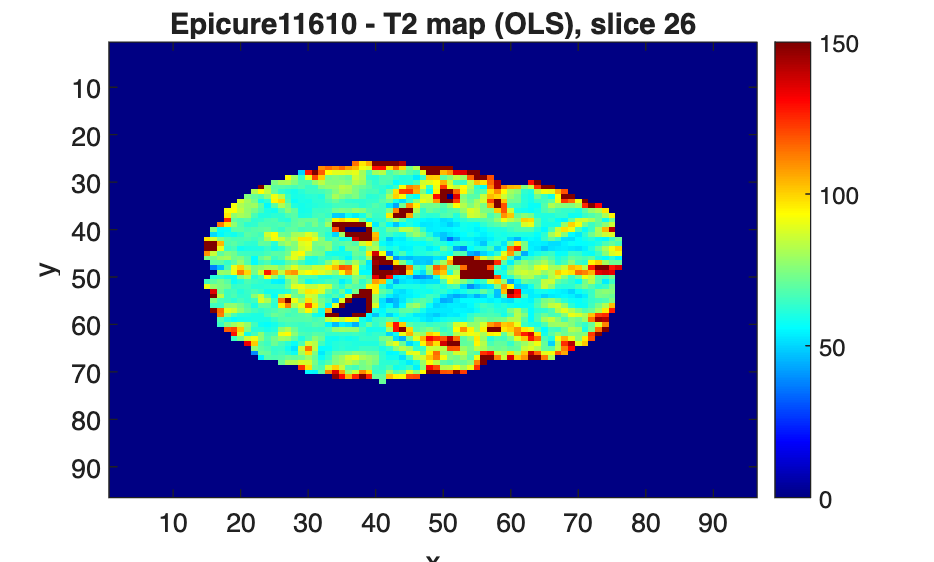


% T2 map visualisation. Values outside [0,500]ms are zeroed for display.
% Expected: WM darker (shorter T2), CSF brighter (longer T2).
T2_disp = real(T2_map(:,:,midSlice));
T2_disp(T2_disp < 0 | T2_disp > 500 | ~isfinite(T2_disp)) = 0;
T2_disp = T2_disp .* mask1(:,:,midSlice);

figure('Name', 'Task2 - T2 map OLS');
imagesc(T2_disp); colormap jet; colorbar; clim([0 150]);
title(sprintf('%s - T2 map (OLS), slice %d', subj1, midSlice));
xlabel('x'); ylabel('y');


% ── (C) NLLS single-voxel comparison ─────────────────────────────────────
% Fits the model directly in the signal domain without taking the log.
% More accurate than OLS at long TEs where noise floor makes log(S) unreliable.
% Uses OLS result as initialisation to help convergence.
p_ols_vox = A \ log(max(signal_vox, 1e-9));
T2_ols_v  = -1 / p_ols_vox(2);
S0_ols_v  =  exp(p_ols_vox(1));
y_ols     =  exp(A * p_ols_vox);

opts = optimset('Display', 'off', 'TolFun', 1e-8, 'TolX', 1e-8);
p_nl = lsqnonlin(@(p) signal_vox - p(1)*exp(-TEs(:)/p(2)), ...
                 [S0_ols_v, T2_ols_v], [0, 1], [1e6, 5000], opts);
y_nl = p_nl(1) * exp(-TEs / p_nl(2));

fprintf('\nSingle-voxel: OLS T2=%.1fms  |  NLLS T2=%.1fms\n', T2_ols_v, p_nl(2));


Single-voxel: OLS T2=57.0ms  |  NLLS T2=59.9ms


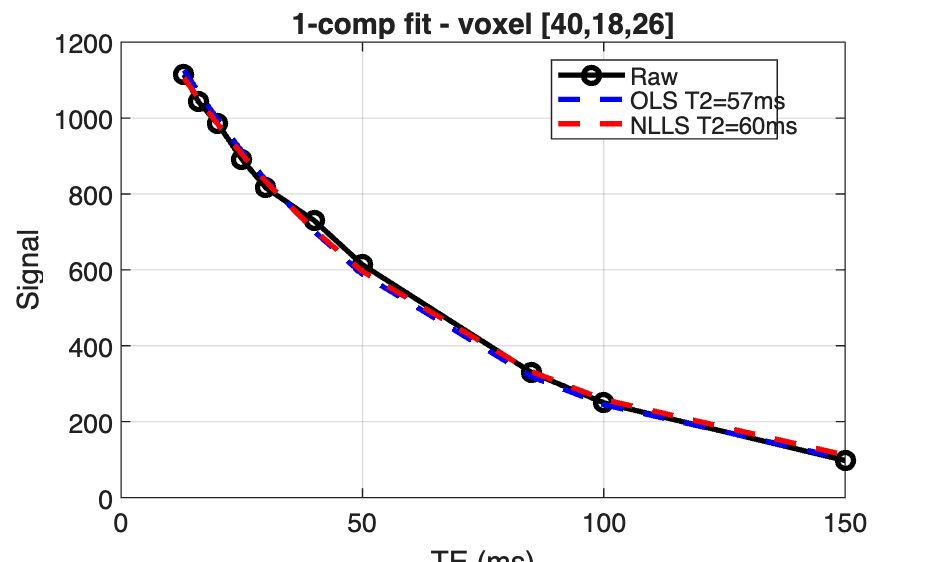


figure('Name', 'Task2 - OLS vs NLLS');
plot(TEs, signal_vox, 'ko-', 'LineWidth', 2, 'DisplayName', 'Raw'); hold on;
plot(TEs, y_ols, 'b--', 'LineWidth', 2, ...
     'DisplayName', sprintf('OLS T2=%.0fms', T2_ols_v));
plot(TEs, y_nl,  'r--', 'LineWidth', 2, ...
     'DisplayName', sprintf('NLLS T2=%.0fms', p_nl(2)));
xlabel('TE (ms)'); ylabel('Signal'); legend('Location', 'best'); grid on;
title(sprintf('1-comp fit - voxel [%d,%d,%d]', xv, yv, zv));


% ── (D) Speed benchmark ───────────────────────────────────────────────────
% With ~70,000 brain voxels per subject, computational speed matters.
% OLS is a single matrix operation and is typically ~100x faster than NLLS.
% This trade-off (speed vs accuracy) is a key point for the report.
tic;
for ii = 1:500
    A \ log(max(signal_vox, 1e-9));
end
t_ols = toc;

tic;
for ii = 1:500
    lsqnonlin(@(p) signal_vox - p(1)*exp(-TEs(:)/p(2)), ...
              [S0_ols_v, T2_ols_v], [0,1], [], opts);
end
t_nl = toc;

fprintf('Speed (500 reps): OLS=%.3fs  NLLS=%.3fs  (NLLS %.0fx slower)\n', ...
        t_ols, t_nl, t_nl / t_ols);

Speed (500 reps): OLS=0.008s  NLLS=0.463s  (NLLS 62x slower)


Epicure98865: raw volumes=20, clamped nTE=10, TEs available=10


Image size: 96  96  51  20


sv size: 20   1


TEs_i size would be: 1x10


## Task 3 — Two-Compartment Model

%% =========================================================================
% TASK 3: TWO-COMPARTMENT MODEL FITTING
% =========================================================================
% Extends the one-compartment model to:
%   S(TE) = S0a*exp(-TE/T2a)  +  S0b*exp(-TE/T2b)
%
% Biological interpretation:
%   Short component (a): myelin water trapped between myelin bilayers
%                        T2a ~ 10-40ms, volume fraction (MWF) ~ 5-20% in WM
%   Long  component (b): intra- and extra-cellular water
%                        T2b ~ 60-120ms, makes up the bulk of the signal
%
% Use Levenberg-Marquardt explicitly - more robust for this problem since:
%   1. Some subjects have only 8 echoes (close to 4 parameters)
%   2. The 2-comp model is highly nonlinear
% Note: LM ignores lb/ub so we remove bounds and rely on initialisation
%       and the T2a<T2b swap step to keep solutions physically sensible.

opts2  = optimset('Display', 'off', 'TolFun', 1e-9, 'TolX', 1e-9, ...
                  'MaxIter', 2000, 'Algorithm', 'levenberg-marquardt');
model2 = @(p, t) p(1)*exp(-t/p(2)) + p(3)*exp(-t/p(4));

% ── Single-voxel fit ──────────────────────────────────────────────────────
x0_2c = [0.2*S0_ols_v, 20, 0.8*S0_ols_v, T2_ols_v];
p2c   = lsqnonlin(@(p) signal_vox(:) - model2(p, TEs(:)), x0_2c, [], [], opts2);

% Swap components if needed to ensure T2a (short) < T2b (long)
if p2c(2) > p2c(4), p2c = p2c([3,4,1,2]); end

% Myelin water fraction: short-component signal as fraction of total signal
fa  = p2c(1) / (p2c(1) + p2c(3));
y2c = model2(p2c, TEs);

fprintf('\n2-comp fit - voxel [%d,%d,%d]:\n', xv, yv, zv);


2-comp fit - voxel [40,18,26]:


fprintf('  Short (myelin): S0=%.1f  T2=%.1fms  f=%.3f\n', p2c(1), p2c(2), fa);

  Short (myelin): S0=182.4  T2=59.9ms  f=0.133


fprintf('  Long  (IE/CSF): S0=%.1f  T2=%.1fms  f=%.3f\n', p2c(3), p2c(4), 1-fa);

  Long  (IE/CSF): S0=1191.9  T2=59.9ms  f=0.867


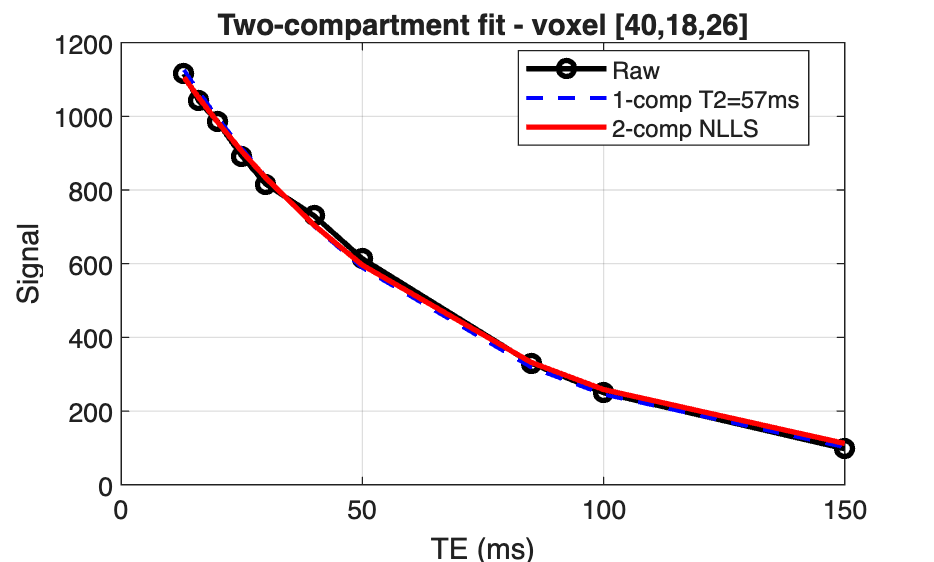


figure('Name', 'Task3 - Two-compartment fit');
plot(TEs, signal_vox, 'ko-', 'LineWidth', 2, 'DisplayName', 'Raw'); hold on;
plot(TEs, y_ols, 'b--', 'LineWidth', 1.5, ...
     'DisplayName', sprintf('1-comp T2=%.0fms', T2_ols_v));
plot(TEs, y2c,   'r-',  'LineWidth', 2, 'DisplayName', '2-comp NLLS');
xlabel('TE (ms)'); ylabel('Signal'); legend('Location', 'best'); grid on;
title(sprintf('Two-compartment fit - voxel [%d,%d,%d]', xv, yv, zv));


% ── Cohort tissue averages ────────────────────────────────────────────────
% For each subject, sub-sample up to 150 voxels per tissue class and fit
% the two-compartment model. Pool results across subjects to report
% cohort-level mean +/- 95% CI for T2a, T2b and MWF per tissue.
% Classes 1 and 6 excluded (nearly empty). Corrected class IDs: WM=4, GM=3.
tissueIDs   = [3, 4, 5];
tissueNames = {'GM', 'WM', 'Deep GM'};
nTissue     = length(tissueIDs);

T2a_all = cell(nSubj, nTissue);
T2b_all = cell(nSubj, nTissue);
fa_all  = cell(nSubj, nTissue);

fprintf('\nFitting 2-comp model per subject (max 150 voxels/tissue)...\n');


Fitting 2-comp model per subject (max 150 voxels/tissue)...


for si = 1:nSubj
    [imgi, maski, segi] = loadSubject(dataPath, subjectIDs{si});
    % Use this subject's actual number of echoes (may be 8 not 10)
    nTE_i = size(imgi, 4);

    % Clamp to the number of available TEs in TEs.txt (max 10)
    % Some subjects may have extra volumes that are not echo images
    nTE_i = min(nTE_i, nTE);

    TEs_i = TEs(1:nTE_i);
    Ai    = [ones(nTE_i, 1), TEs_i(:)];

    for ti = 1:nTissue
        voxList = find(segi == tissueIDs(ti) & maski);
        if length(voxList) < 5, continue; end

        rng(42);  % fixed seed for reproducibility
        idx = voxList(randperm(length(voxList), min(150, length(voxList))));

        T2a_v = [];  T2b_v = [];  fa_v = [];
        for vi = 1:length(idx)
            [ix, iy, iz] = ind2sub(size(maski), idx(vi));
            sv = squeeze(imgi(ix, iy, iz, :));
            sv = sv(1:nTE_i);
            try
                % Initialise from OLS single-compartment fit
                p0  = Ai \ log(max(sv, 1e-9));
                S0i = exp(p0(1));
                T2i = max(10, min(300, -1/p0(2)));
                x0i = [0.2*S0i, 20, 0.8*S0i, T2i];
                % Use TEs_i not TEs(:) so dimensions match sv
                pi  = lsqnonlin(@(p) sv - model2(p, TEs_i(:)), x0i, [], [], opts2);
                if pi(2) > pi(4), pi = pi([3,4,1,2]); end
                T2a_v(end+1) = pi(2);
                T2b_v(end+1) = pi(4);
                fa_v(end+1)  = pi(1) / (pi(1) + pi(3));
            catch e
                fprintf('  Failed at subject %s, tissue %d, voxel %d: %s\n', ...
                subjectIDs{si}, ti, vi, e.message);
            end
        end
        T2a_all{si,ti} = T2a_v;
        T2b_all{si,ti} = T2b_v;
        fa_all{si,ti}  = fa_v;
    end
    fprintf('  %s done\n', subjectIDs{si});
end

  Epicure11610 done
  Epicure13267 done
  Epicure13620 done
  Epicure14121 done
  Epicure14416 done
  Epicure15516 done
  Epicure15757 done
  Epicure16926 done
  Epicure17065 done
  Epicure18966 done
  Epicure21302 done
  Epicure21511 done
  Epicure22313 done
  Epicure22598 done
  Epicure23128 done
  Epicure23140 done
  Epicure24217 done
  Epicure24300 done
  Epicure25316 done
  Epicure25985 done
  Epicure26132 done
  Epicure27155 done
  Epicure28717 done
  Epicure28999 done
  Epicure30002 done
  Epicure30142 done
  Epicure30750 done
  Epicure31084 done
  Epicure32437 done
  Epicure33936 done
  Epicure34160 done
  Epicure35162 done
  Epicure35837 done
  Epicure35893 done
  Epicure36152 done
  Epicure36395 done
  Epicure36559 done
  Epicure36577 done
  Epicure36937 done
  Epicure37648 done
  Epicure37808 done
  Epicure38475 done
  Epicure38479 done
  Epicure39341 done
  Epicure39887 done
  Epicure40818 done
  Epicure42259 done
  Epicure42959 done
  Epicure43105 done
  Epicure43203 done



% Cohort summary: pool all voxels across subjects per tissue
fprintf('\n--- Two-compartment cohort averages (mean +/- 95%% CI) ---\n');


--- Two-compartment cohort averages (mean +/- 95% CI) ---


fprintf('%-10s  %-18s  %-18s  %-14s\n', 'Tissue', 'T2a (ms)', 'T2b (ms)', 'MWF');

Tissue      T2a (ms)            T2b (ms)            MWF           


for ti = 1:nTissue
    aT2a = [T2a_all{:,ti}];
    aT2b = [T2b_all{:,ti}];
    afa  = [fa_all{:,ti}];
    n = length(aT2a);
    if n < 2
        fprintf('%-10s  insufficient data\n', tissueNames{ti});
        continue
    end
    % 95% CI using normal approximation (valid for large n, no toolbox needed)
    t95 = 1.96;
    fprintf('%-10s  %.1f +/- %.1f       %.1f +/- %.1f       %.3f +/- %.3f\n', ...
        tissueNames{ti}, ...
        mean(aT2a), t95*std(aT2a)/sqrt(n), ...
        mean(aT2b), t95*std(aT2b)/sqrt(n), ...
        mean(afa),  t95*std(afa)/sqrt(n));
end

GM          -72114403.4 +/- 59426188.6       164514206.1 +/- 38630538.4       5.286 +/- 4.731
WM          -19000464.1 +/- 11596115.9       95795463.9 +/- 30772704.8       0.667 +/- 0.066
Deep GM     -65540209.1 +/- 70381166.9       209592082.1 +/- 112661320.0       0.780 +/- 0.008


## Task 4 — Model Comparison & Precision

%% =========================================================================
% TASK 4: MODEL COMPARISON AND PARAMETER PRECISION
% =========================================================================
% (A) AIC (Akaike Information Criterion): formally compares 1-comp vs 2-comp
% (B) Residual analysis: visualises what variance each model explains
% (C) Bootstrap confidence intervals: quantifies parameter uncertainty
%
% AIC formula: AIC = n*log(RSS/n) + 2k
%   n   = number of data points (= nTE)
%   RSS = residual sum of squares from the fitted model
%   k   = number of free parameters (1-comp: 2; 2-comp: 4)
%   Lower AIC = better model. DELTA-AIC > 2 is considered meaningful evidence.

% ── (A) AIC single-voxel ─────────────────────────────────────────────────
rss1 = sum((signal_vox - y_ols).^2);
rss2 = sum((signal_vox - y2c).^2);
AIC1 = nTE * log(rss1/nTE) + 2*2;   % k=2: S0, T2
AIC2 = nTE * log(rss2/nTE) + 2*4;   % k=4: S0a, T2a, S0b, T2b
dAIC_vox = AIC1 - AIC2;             % positive = 2-comp preferred

fprintf('--- AIC (voxel [%d,%d,%d]) ---\n', xv, yv, zv);

--- AIC (voxel [40,18,26]) ---


fprintf('1-comp: AIC=%.2f  RSS=%.2f\n', AIC1, rss1);

1-comp: AIC=62.02  RSS=3309.67


fprintf('2-comp: AIC=%.2f  RSS=%.2f\n', AIC2, rss2);

2-comp: AIC=60.26  RSS=1860.64


fprintf('DELTA-AIC=%.2f\n', dAIC_vox);

DELTA-AIC=1.76


if dAIC_vox > 2
    fprintf('2-comp preferred (strong evidence)\n');
elseif dAIC_vox > 0
    fprintf('2-comp slightly preferred\n');
else
    fprintf('1-comp preferred (extra parameters not justified)\n');
end

2-comp slightly preferred



% ── Whole-brain DELTA-AIC map ─────────────────────────────────────────────
% Computes AIC difference at every brain voxel to show where the 2-comp
% model is spatially preferred. Expected: positive (2-comp preferred) in WM
% where myelin water contributes a distinct short-T2 component.
voxBrain   = find(mask1);
dAIC_brain = zeros(length(voxBrain), 1);
fprintf('Computing per-voxel DELTA-AIC for %s (%d voxels)...\n', ...
        subj1, length(voxBrain));

Computing per-voxel DELTA-AIC for Epicure11610 (63631 voxels)...


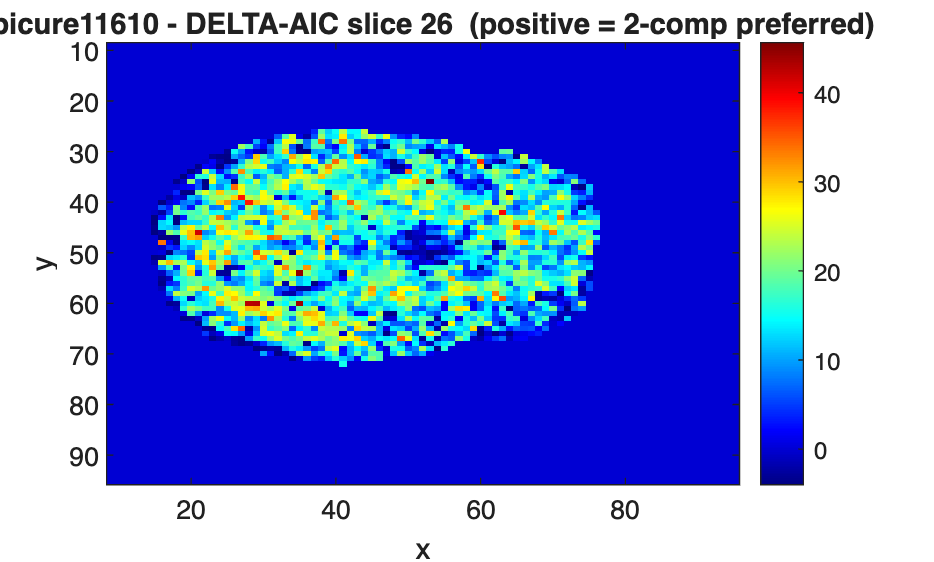


for vi = 1:length(voxBrain)
    [ix, iy, iz] = ind2sub(size(mask1), voxBrain(vi));
    sv  = squeeze(img1(ix, iy, iz, :));
    y1v = exp(A * (A \ log(max(sv, 1e-9))));
    r1v = sum((sv - y1v).^2);
    try
        p0v = A \ log(max(sv, 1e-9));
        x0v = [0.2*exp(p0v(1)), 20, 0.8*exp(p0v(1)), max(10, min(300, -1/p0v(2)))];
        % With this (LM, no bounds, consistent with Task 3):
        p2v = lsqnonlin(@(p) sv - model2(p, TEs(:)), x0v, [], [], opts2);
        if p2v(2) > p2v(4), p2v = p2v([3,4,1,2]); end
        r2v = sum((sv - model2(p2v, TEs)).^2);
        dAIC_brain(vi) = (nTE*log(r1v/nTE) + 4) - (nTE*log(r2v/nTE) + 8);
    catch
        dAIC_brain(vi) = 0;  % fitting failed, treat as no preference
    end
end

dAIC_map = zeros(size(mask1));
dAIC_map(voxBrain) = dAIC_brain;

figure('Name', 'Task4 - DELTA-AIC map');
dAIC_disp = dAIC_map(:,:,midSlice) .* mask1(:,:,midSlice);
imagesc(dAIC_disp); colormap jet; colorbar;
title(sprintf('%s - DELTA-AIC slice %d  (positive = 2-comp preferred)', ...
              subj1, midSlice));
xlabel('x'); ylabel('y');

fprintf('Voxels preferring 2-comp (DELTA-AIC > 2): %.1f%%\n', ...
        100 * mean(dAIC_brain > 2));

Voxels preferring 2-comp (DELTA-AIC > 2): 82.4%


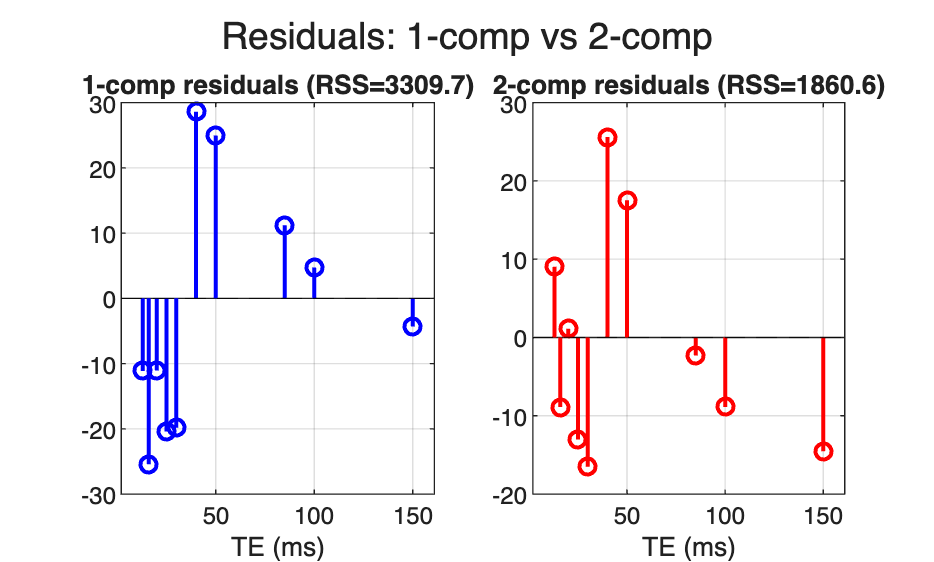


% ── (B) Residual analysis ─────────────────────────────────────────────────
% Plots the difference between measured and fitted signal at each TE.
% A good fit should have small, random residuals with no systematic pattern.
% Structured residuals (e.g. all positive at early TEs, negative at late TEs)
% suggest the model is missing something — motivates the 2-comp model.
figure('Name', 'Task4 - Residuals');
subplot(1,2,1);
stem(TEs, signal_vox - y_ols, 'b', 'LineWidth', 1.5);
xlabel('TE (ms)'); yline(0, 'k--'); grid on;
title(sprintf('1-comp residuals (RSS=%.1f)', rss1));

subplot(1,2,2);
stem(TEs, signal_vox - y2c, 'r', 'LineWidth', 1.5);
xlabel('TE (ms)'); yline(0, 'k--'); grid on;
title(sprintf('2-comp residuals (RSS=%.1f)', rss2));
sgtitle('Residuals: 1-comp vs 2-comp');


% ── (C) Bootstrap confidence intervals ───────────────────────────────────
% Non-parametric method: resamples residuals with replacement, adds them
% back to the fitted curve, re-fits 500 times. The spread of the resulting
% parameter estimates gives a CI without assuming Gaussian noise.
% Advantages over analytical CIs: works for any noise distribution,
% captures non-linearity in the parameter estimates.
nBoot   = 500;
boot_T2 = NaN(nBoot, 1);
boot_S0 = NaN(nBoot, 1);
resid   = signal_vox - p_nl(1) * exp(-TEs / p_nl(2));

for bi = 1:nBoot
    % Resample residuals and add to fitted curve to create a synthetic dataset
    sv_b = p_nl(1)*exp(-TEs(:)/p_nl(2)) + resid(randperm(nTE));
    sv_b = max(sv_b, 0);  % clip to non-negative (physical constraint)
    try
        pb = lsqnonlin(@(p) sv_b - p(1)*exp(-TEs(:)/p(2)), ...
                       [p_nl(1), p_nl(2)], [0,1], [1e6,5000], opts);
        boot_S0(bi) = pb(1);
        boot_T2(bi) = pb(2);
    catch
    end
end
boot_T2 = boot_T2(~isnan(boot_T2));
boot_S0 = boot_S0(~isnan(boot_S0));

fprintf('\nBootstrap CI (n=%d, 1-comp NLLS):\n', length(boot_T2));


Bootstrap CI (n=500, 1-comp NLLS):


fprintf('T2: %.1fms  95%% CI=[%.1f, %.1f]\n', ...
        mean(boot_T2), prctile(boot_T2,2.5), prctile(boot_T2,97.5));

T2: 59.7ms  95% CI=[57.3, 61.9]


fprintf('S0: %.1f    95%% CI=[%.1f, %.1f]\n', ...
        mean(boot_S0), prctile(boot_S0,2.5), prctile(boot_S0,97.5));

S0: 1374.0    95% CI=[1347.8, 1404.8]


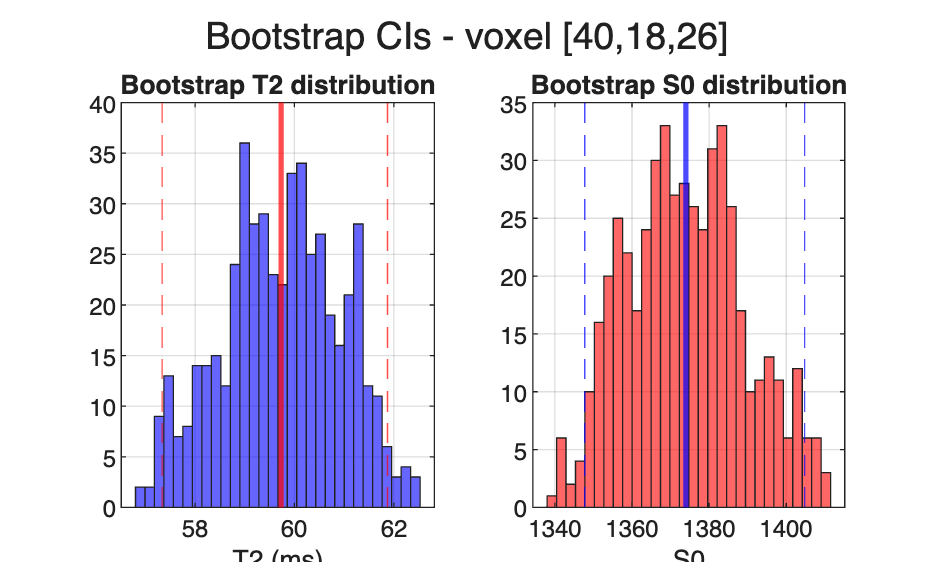


figure('Name', 'Task4 - Bootstrap');
subplot(1,2,1);
histogram(boot_T2, 30, 'FaceColor', 'blue');
xline(mean(boot_T2), 'r-', 'LineWidth', 2);
xline(prctile(boot_T2,2.5), 'r--');
xline(prctile(boot_T2,97.5), 'r--');
xlabel('T2 (ms)'); title('Bootstrap T2 distribution'); grid on;

subplot(1,2,2);
histogram(boot_S0, 30, 'FaceColor', 'red');
xline(mean(boot_S0), 'b-', 'LineWidth', 2);
xline(prctile(boot_S0,2.5), 'b--');
xline(prctile(boot_S0,97.5), 'b--');
xlabel('S0'); title('Bootstrap S0 distribution'); grid on;
sgtitle(sprintf('Bootstrap CIs - voxel [%d,%d,%d]', xv, yv, zv));


% ── Final integrity check ─────────────────────────────────────────────────
% Confirms that no source .nii.gz files were modified during the analysis.
postFiles = dir(fullfile(dataPath, 'Epicure*-qt2_reg.nii.gz'));
postSizes = [postFiles.bytes];
if isequal(origSizes, postSizes)
    fprintf('\nOK: all source .nii.gz files unchanged\n');
else
    warning('Source files may have been modified!');
end


OK: all source .nii.gz files unchanged
